j = [1];
figure

splitfolder=strcat('split',num2str(j));
per =0;%[50,40,30,20,10,5,2,0];
percent = per;
cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
cd (splitfolder)

folder=strcat('per',num2str(percent));
cd (folder)
my_file = strcat('cell_sample_misclass_per_',num2str(percent),'.csv');
File=readmatrix(my_file,"NumHeaderLines",1);

benign=File(File(:,10)==2,1:9);
T_benign=benign.';
malignant=File(File(:,10)==4,1:9);
T_malignant=malignant.';

% folder_l1=strcat('ACE_dist_3optrank_angle_l1pca_per',num2str(percent));
% mkdir (folder_l1)

ranks=1; [1,2,3,5,6,7,8];

error_benign = nan(size(ranks));
numbenign=length(T_benign);
Dist_mat_benign_array=nan(length(ranks),numbenign);
threshold_rank_b=nan(size(ranks));
elbow_indx_rank_b=nan(size(ranks));

 i = ranks;
    %fprintf("Rank is %i \n", i) %i);
    cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering\

    T_benign_temp=T_benign;
    Dist_mat_benign=[];


    BF_benign=l1pca_BF(T_benign,i,1,10,10,'');
    for k = 1 : numbenign
        A=T_benign(:,k);
        Dist_mat_benign(k)=norm((A-(BF_benign*BF_benign.'*A)),1);
        k;
    end

    min_val=min(Dist_mat_benign,[],"all");
    max_val=max(Dist_mat_benign,[],"all");
    Dist_mat_benign= Dist_mat_benign-min_val;%]/[max_val-min_val]
    Dist_mat_benign=Dist_mat_benign /(max_val-min_val);


    Dist_mat_benign_array(i,:)=Dist_mat_benign;
    [Dist_mat_benign_asc,Indx_b]=sort(Dist_mat_benign,"ascend");

    y = Dist_mat_benign_asc(:);

    x = (1:length(y))';


    idx = 1:length(x);

    %the code below "unwraps" the repeated regress(y,x) calls.  It's
    %significantly faster than the former for longer y's
    %
    %figure out the m and b (in the y=mx+b sense) for the "left-of-knee"
    sigma_xy = cumsum(x.*y);
    sigma_x  = cumsum(x);
    sigma_y  = cumsum(y);
    sigma_xx = cumsum(x.*x);
    n        = (1:length(y))';
    det = n.*sigma_xx-sigma_x.*sigma_x;
    mfwd = (n.*sigma_xy-sigma_x.*sigma_y)./det;
    bfwd = -(sigma_x.*sigma_xy-sigma_xx.*sigma_y) ./det;

    %figure out the m and b (in the y=mx+b sense) for the "right-of-knee"
    sigma_xy = cumsum(x(end:-1:1).*y(end:-1:1));
    sigma_x  = cumsum(x(end:-1:1));
    sigma_y  = cumsum(y(end:-1:1));
    sigma_xx = cumsum(x(end:-1:1).*x(end:-1:1));
    n        = (1:length(y))';
    det = n.*sigma_xx-sigma_x.*sigma_x;
    mbck = flipud((n.*sigma_xy-sigma_x.*sigma_y)./det);
    bbck = flipud(-(sigma_x.*sigma_xy-sigma_xx.*sigma_y) ./det);

    %figure out the sum of per-point errors for left- and right- of-knee fits




    angle_threshold=nan(size(y));
    error_curve=nan(size(y));
    for breakpt = 2:length(y-1)
        delsfwd = (mfwd(breakpt).*x(1:breakpt)+bfwd(breakpt))-y(1:breakpt);
        delsbck = (mbck(breakpt).*x(breakpt:end)+bbck(breakpt))-y(breakpt:end);
        error_curve(breakpt) = sum(abs(delsfwd))+ sum(abs(delsbck));

        theta= ((mbck(breakpt)-mfwd(breakpt))/(1+((mfwd(breakpt)* mbck(breakpt)))));
        %(mfwd(breakpt)-mbck(breakpt))/(1+((mfwd(breakpt)* mbck(breakpt))));
        angle=atand((theta))
        
        angle_threshold(breakpt)=rad2deg((angle));
    end

angle = 0.0795

angle = 0.0797

angle = 0.0799

angle = 0.0802

angle = 0.0804

angle = 0.0684

angle = 0.0645

angle = 0.0639

angle = 0.0647

angle = 0.0660

angle = 0.0674

angle = 0.0688

angle = 0.0702

angle = 0.0714

angle = 0.0726

angle = 0.0736

angle = 0.0746

angle = 0.0755

angle = 0.0760

angle = 0.0765

angle = 0.0770

angle = 0.0776

angle = 0.0781

angle = 0.0786

angle = 0.0791

angle = 0.0795

angle = 0.0784

angle = 0.0758

angle = 0.0681

angle = 0.0620

angle = 0.0572

angle = 0.0534

angle = 0.0504

angle = 0.0482

angle = 0.0465

angle = 0.0453

angle = 0.0437

angle = 0.0425

angle = 0.0417

angle = 0.0412

angle = 0.0409

angle = 0.0407

angle = 0.0386

angle = 0.0369

angle = 0.0349

angle = 0.0333

angle = 0.0321

angle = 0.0307

angle = 0.0296

angle = 0.0289

angle = 0.0284

angle = 0.0281

angle = 0.0281

angle = 0.0282

angle = 0.0285

angle = 0.0283

angle = 0.0283

angle = 0.0285

angle = 0.0288

angle = 0.0293

angle = 0.0299

angle = 0.0305

angle = 0.0313

angle = 0.0320

angle = 0.0328

angle = 0.0336

angle = 0.0346

angle = 0.0356

angle = 0.0366

angle = 0.0376

angle = 0.0388

angle = 0.0399

angle = 0.0410

angle = 0.0422

angle = 0.0434

angle = 0.0446

angle = 0.0459

angle = 0.0471

angle = 0.0484

angle = 0.0496

angle = 0.0509

angle = 0.0519

angle = 0.0529

angle = 0.0539

angle = 0.0549

angle = 0.0560

angle = 0.0571

angle = 0.0582

angle = 0.0593

angle = 0.0604

angle = 0.0615

angle = 0.0626

angle = 0.0637

angle = 0.0649

angle = 0.0660

angle = 0.0671

angle = 0.0683

angle = 0.0695

angle = 0.0706

angle = 0.0718

angle = 0.0730

angle = 0.0741

angle = 0.0753

angle = 0.0765

angle = 0.0777

angle = 0.0789

angle = 0.0800

angle = 0.0812

angle = 0.0824

angle = 0.0835

angle = 0.0846

angle = 0.0857

angle = 0.0869

angle = 0.0879

angle = 0.0889

angle = 0.0898

angle = 0.0908

angle = 0.0918

angle = 0.0928

angle = 0.0938

angle = 0.0949

angle = 0.0959

angle = 0.0970

angle = 0.0981

angle = 0.0992

angle = 0.1002

angle = 0.1013

angle = 0.1025

angle = 0.1036

angle = 0.1047

angle = 0.1059

angle = 0.1070

angle = 0.1082

angle = 0.1094

angle = 0.1106

angle = 0.1118

angle = 0.1130

angle = 0.1142

angle = 0.1154

angle = 0.1166

angle = 0.1178

angle = 0.1190

angle = 0.1202

angle = 0.1214

angle = 0.1226

angle = 0.1238

angle = 0.1250

angle = 0.1262

angle = 0.1275

angle = 0.1287

angle = 0.1299

angle = 0.1310

angle = 0.1323

angle = 0.1336

angle = 0.1348

angle = 0.1361

angle = 0.1374

angle = 0.1387

angle = 0.1400

angle = 0.1412

angle = 0.1426

angle = 0.1439

angle = 0.1454

angle = 0.1468

angle = 0.1483

angle = 0.1498

angle = 0.1514

angle = 0.1529

angle = 0.1545

angle = 0.1561

angle = 0.1577

angle = 0.1593

angle = 0.1610

angle = 0.1627

angle = 0.1644

angle = 0.1662

angle = 0.1681

angle = 0.1700

angle = 0.1720

angle = 0.1740

angle = 0.1760

angle = 0.1781

angle = 0.1802

angle = 0.1823

angle = 0.1845

angle = 0.1867

angle = 0.1890

angle = 0.1914

angle = 0.1938

angle = 0.1964

angle = 0.1990

angle = 0.2018

angle = 0.2046

angle = 0.2074

angle = 0.2103

angle = 0.2133

angle = 0.2164

angle = 0.2195

angle = 0.2228

angle = 0.2261

angle = 0.2295

angle = 0.2331

angle = 0.2367

angle = 0.2405

angle = 0.2443

angle = 0.2483

angle = 0.2524

angle = 0.2565

angle = 0.2607

angle = 0.2650

angle = 0.2694

angle = 0.2738

angle = 0.2783

angle = 0.2829

angle = 0.2877

angle = 0.2927

angle = 0.2978

angle = 0.3029

angle = 0.3082

angle = 0.3135

angle = 0.3189

angle = 0.3244

angle = 0.3301

angle = 0.3358

angle = 0.3419

angle = 0.3483

angle = 0.3547

angle = 0.3613

angle = 0.3681

angle = 0.3749

angle = 0.3818

angle = 0.3888

angle = 0.3962

angle = 0.4041

angle = 0.4129

angle = 0.4221

angle = 0.4317

angle = 0.4415

angle = 0.4518

angle = 0.4624

angle = 0.4736

angle = 0.4851

angle = 0.4969

angle = 0.5091

angle = 0.5217

angle = 0.5347

angle = 0.5480

angle = 0.5622

angle = 0.5766

angle = 0.5918

angle = 0.6073

angle = 0.6233

angle = 0.6405

angle = 0.6580

angle = 0.6759

angle = 0.6950

angle = 0.7147

angle = 0.7356

angle = 0.7568

angle = 0.7782

angle = 0.7997

angle = 0.8212

angle = 0.8436

angle = 0.8657

angle = 0.8898

angle = 0.9138

angle = 0.9386

angle = 0.9649

angle = 1.0010

angle = 1.0386

angle = 1.0766

angle = 1.1214

angle = 1.1697

angle = 1.2207

angle = 1.2723

angle = 1.3284

angle = 1.3848

angle = 1.4403

angle = 1.5051

angle = 1.5693

angle = 1.6371

angle = 1.7148

angle = 1.7965

angle = 1.9042

angle = 2.0551

angle = 2.2107

angle = 2.4429

angle = 2.6965

angle = 2.9782

angle = 3.2537

angle = 3.7401

angle = 4.3489

angle = 4.9604

angle = 5.5548

angle = 5.2981

angle = 6.3011

angle = 2.1664

angle = NaN


    %find location of the min of the error curve
    [~,loc] = min(error_curve)

loc = 260


    x1=x(1: 290);%(loc)) ;
    y1=mfwd(loc).* x1 + bfwd(loc);

    x2=x(230:299);
    y2=mbck(loc).*x2+bbck(loc);


 

      
    y(loc)

ans = 0.2544

%    plot(x1,y1,"c")
%     hold on
%     plot(x2,y2,"g")
%     hold on
    angle_x =(angle_threshold(loc))% x(loc);

angle_x = 43.3629

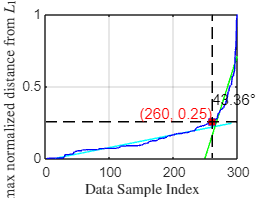

%idx=find(angle_threshold==res_x);
elbow_indx_b =idx(loc);

x2_resampled = linspace(min(x2), max(x2), numel(x1));
y2_resampled = interp1(x2, y2, x2_resampled);

 % Plot the two data series
figure;
plot(x1, y1, "c");
hold on;
plot(x2_resampled, y2_resampled, "g");
   
         
                plot((Dist_mat_benign_asc),'-bs',"MarkerIndices",(elbow_indx_b),'MarkerFaceColor','red','MarkerSize',6 )
                xlabel("index, p")
                ylabel(["Distance of samples from L1 subspace",num2str(i)])
               % title(['Rank, k =',num2str(i) ])
               line([elbow_indx_b, elbow_indx_b], ylim, 'Color', 'k', 'LineStyle', '--');
               line(xlim, [Dist_mat_benign_asc(elbow_indx_b), Dist_mat_benign_asc(elbow_indx_b)], 'Color', 'k', 'LineStyle', '--');
% Display coordinates of elbow_indx_b
x_coord = elbow_indx_b;
y_coord = Dist_mat_benign_asc(elbow_indx_b);
formatted_text = ['(', num2str(round(x_coord, 2)), ', ', num2str(round(y_coord, 2)), ')'];
text(x_coord, y_coord, formatted_text, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
% % Create and fill the area between the two lines
% x_fill = [x1, fliplr(x2_resampled)];
% y_fill = [y1, fliplr(y2_resampled)];
% fill(x_fill, y_fill, [0.8 0.8 0.8], 'EdgeColor', 'none');
               grid on
            



                % Calculate the angle between the lines in degrees
%angle_x = rad2deg(angle_threshold(loc));
% 
% % Resample or interpolate x2 to match the dimensions of x1
% x2_resampled = linspace(min(x2), max(x2), numel(x1));
% y2_resampled = interp1(x2, y2, x2_resampled);
% 
% % Plot the two data series
% figure;
% plot(x1, y1, "c");
% hold on;
% plot(x2_resampled, y2_resampled, "g");

% Create and fill the area between the two lines
x_fill = [x1, (x2_resampled).'];
y_fill = [y1, (y2_resampled).'];
fill(x_fill, y_fill, [1 0.15 0.95], 'EdgeColor', 'none');

% % Plot the marker and dotted line at the elbow index
% scatter(elbow_indx_b, Dist_mat_benign_asc(elbow_indx_b), 100, 'red', 'filled');
% line([elbow_indx_b, elbow_indx_b], ylim, 'Color', 'k', 'LineStyle', '--');
% line(xlim, [Dist_mat_benign_asc(elbow_indx_b), Dist_mat_benign_asc(elbow_indx_b)], 'Color', 'k', 'LineStyle', '--');
% 
% % Display coordinates of elbow_indx_b
% x_coord = elbow_indx_b;
% y_coord = Dist_mat_benign_asc(elbow_indx_b);
% formatted_text_coord = ['(', num2str(round(x_coord, 3)), ', ', num2str(round(y_coord, 3)), ')'];

% Display angle over the curve
text((x1(end) + x2_resampled(end)) / 2, (y1(end) + y2_resampled(end)) / 2,[ num2str(round(angle_x, 2)), '°'],'VerticalAlignment', 'cap', 'HorizontalAlignment', 'center', 'Color', 'black');

xlabel(["Data Sample Index"], 'Interpreter', 'latex');
ylabel(["Min-max normalized distance from $L_1$ subspace"],'Interpreter', 'latex');
% title("Plot with Elbow Point, Coordinates, and Angle over Curve");

% Set axis limits to start from (0,0)
xlim([0, 300]);
ylim([0, 1]); %max([y1,(y2_resampled).', Dist_mat_benign_asc(elbow_indx_b)])]);

grid on;
hold off;



                    %             [elbow_b_err_angle,elbow_indx_b]=knee_pt_angle_test((Dist_mat_benign_asc));
    %
    %             error_benign(i)=elbow_b_err_angle;
    %             threshold_rank_b(i)=Dist_mat_benign_asc(elbow_indx_b);
    %             elbow_indx_rank_b(i)=elbow_indx_b;
    %
    %
       
    %
    %
    %         end
    %
    %
    %         error_benign
    %
    %         [~,optrank_b]= max(error_benign)
    %
    %         Dist_mat_benign_opt=Dist_mat_benign_array(optrank_b,:);
    %         threshold_dist_b= threshold_rank_b(optrank_b);
    %         elbow_indx_b_opt=elbow_indx_rank_b(optrank_b);
    %
    %         ind_O_b=find(Dist_mat_benign_opt>threshold_dist_b);
    %         ind_I_b=find(Dist_mat_benign_opt<=threshold_dist_b);
    %
    %
    %         cluster_b=zeros(size(Dist_mat_benign_opt));
    %         cluster_b(ind_I_b)=1;
    %         figure
    %         y= 1:1:length(benign);
    %         numGroups = length(unique(cluster_b));
    %         gscatter(y,Dist_mat_benign_opt,cluster_b,hsv(numGroups))
    %
    %         figure
    %         plot(sort(Dist_mat_benign_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_b_opt),'MarkerFaceColor','red','MarkerSize',10 )
    %         xlabel("index")
    %         ylabel(["Distance Benign Asc for opt rank" ,num2str(optrank_b)])
    %         title(['Rank opt for Benign =',num2str(optrank_b),"Split=",num2str(j)])
    %         ind_O_b;
    %
    %
    %         T_benign_temp(:,ind_O_b)=[];
    %         length(T_benign_temp);
    %
    %         Final_benign=T_benign_temp';
    %         Final_benign(:,10)=2;
    %
    %     end
    %     %
    %
    %    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




